clear all;


load idealECG.mat;
load nECG.mat;

fs = 128;
N = length(idealECG);
t = (0:N-1)/fs;

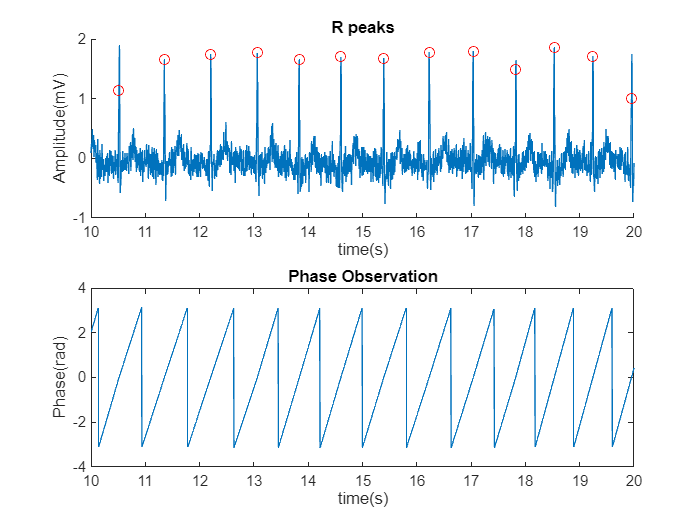

R_peaks = pan_tompkin(nECG,fs,0);
phi = zeros(N,1);
phi(1:R_peaks(1)) = linspace(pi,2*pi,R_peaks(1));

% figure(1);
% clf;
% hold on;
% plot(t, nECG);
% scatter(t(R_peaks),nECG(R_peaks),'r');
% xlim([10,20]);
% hold off;
% saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\R_peaks.png');

for i = 1: length(R_peaks)-1
    phi(R_peaks(i):R_peaks(i+1)) = linspace(0,2*pi,R_peaks(i+1)-R_peaks(i)+1);
end
phi = mod(phi+pi,2*pi)-pi;

figure(1);
subplot(2,1,1);
% clf;
hold on;
plot(t, nECG);
scatter(t(R_peaks),nECG(R_peaks),'r');
hold off;
title('R peaks');
xlim([10,20]);
xlabel('time(s)');
ylabel('Amplitude(mV)');


subplot(2,1,2);
plot(t,phi);
title('Phase Observation');
xlabel('time(s)');
ylabel('Phase(rad)');
xlim([10,20]);
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Phase_obseravation.png');

 T = (R_peaks(length(R_peaks))-R_peaks(1))/(length(R_peaks)-1);
omega = 2*pi/T;

D_t = 1/fs;

% ECG modelling parameters

% theta_i = [2*pi/3, 11*pi/12, pi, 13*pi/12, 3*pi/2];
theta_i = [-1*pi/3, -1*pi/12, 0, pi/12, pi/2];
a_i = [1.2, -5, 30, -7.5, 0.75]*20;
b_i = [0.25, 0.1, 0.1, 0.1, 0.4];

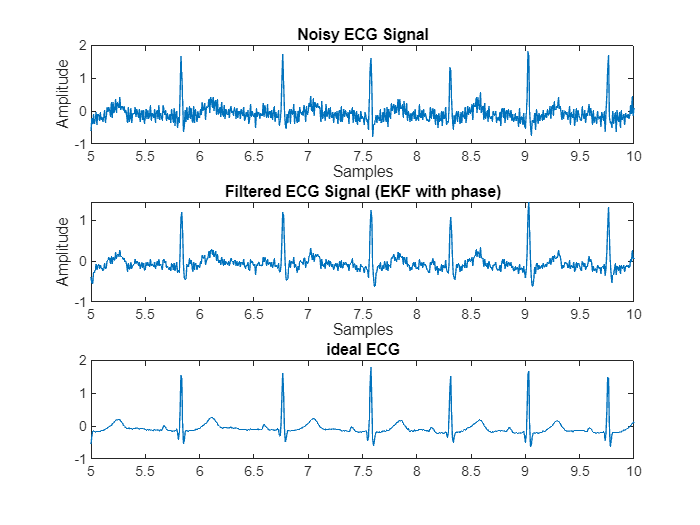

% EKF

Theta = zeros(size(nECG));
z = zeros(size(nECG));

R = [1, 0; 0, 1 ]*0.01;
Q = [1, 0; 0, 1 ];
sigma = eye(2)*1;

C = eye(2);
Theta(1) = -pi;
for n = (2:N)

%%%%%%%%% Prediction %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    Theta(n) = mod(Theta(n-1) + omega*D_t+pi,2*pi)-pi;
    z_dot = 0;
    for i = (1:5)
        D_theta = Theta(n)-theta_i(i);
        z_dot = z_dot - a_i(i)*D_theta*exp(-0.5*D_theta^2/b_i(i)^2);
    end
    z(n) = z(n-1) + D_t*z_dot;
    s = [Theta(n), z(n)]';

%%%%%%%%% Jacobian of state transition %%%%%%%%%%%%%%%%%%%%%%% 
       
    G = eye(2);

    for i = (1:5)
        D_theta = Theta(n)-theta_i(i);
        G(2,1) = G(2,1) - D_t * a_i(i)*(1 - D_theta^2 / b_i(i)^2) * exp(-0.5*D_theta^2 / b_i(i)^2);
    end

%%%%%%%%% Error covariance of prediction %%%%%%%%%%%%%%%%%%%%%
    sigma = G*sigma*G' + R;

%%%%%%%%% Kalman Gain %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    K = sigma*C'/(C*sigma*C' + Q);

%%%%%%%%% Correction using input signal %%%%%%%%%%%%%%%%%%%%%%
    s = s + K*(nECG(n) -C*s);
    Theta(n) = s(1);
    z(n) = s(2);
    sigma = (eye(2) - K*C)*sigma;
end

figure(2);
clf;
subplot(3, 1, 1);
plot(t,nECG);
title('Noisy ECG Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([5,10]);

subplot(3, 1, 2);
plot(t,z);
title('Filtered ECG Signal (EKF with phase)');
xlabel('Samples');
ylabel('Amplitude');
xlim([5 10]);

subplot(3,1,3);
plot(t,idealECG);
xlim([5,10]);
title('ideal ECG');
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Filtered_EKF_phaseS.png');

MSE = mean((z- idealECG).^2)

MSE = 0.0186